# Economics Homework 1

## Question 1:

Code:

% Define vector X
x=[1, 1.5, 3, 4, 5, 7, 9, 10];

% Compute The Values for y1=-2 + 0.5x
y1=-2 + 0.5.*x;

% Display y1
disp(y1')

   -1.5000
   -1.2500
   -0.5000
         0
    0.5000
    1.5000
    2.5000
    3.0000



% Compute the values for y2
y2= -2 + 0.5 .* x.^2;

% Display y2
disp(y2')

   -1.5000
   -0.8750
    2.5000
    6.0000
   10.5000
   22.5000
   38.5000
   48.0000



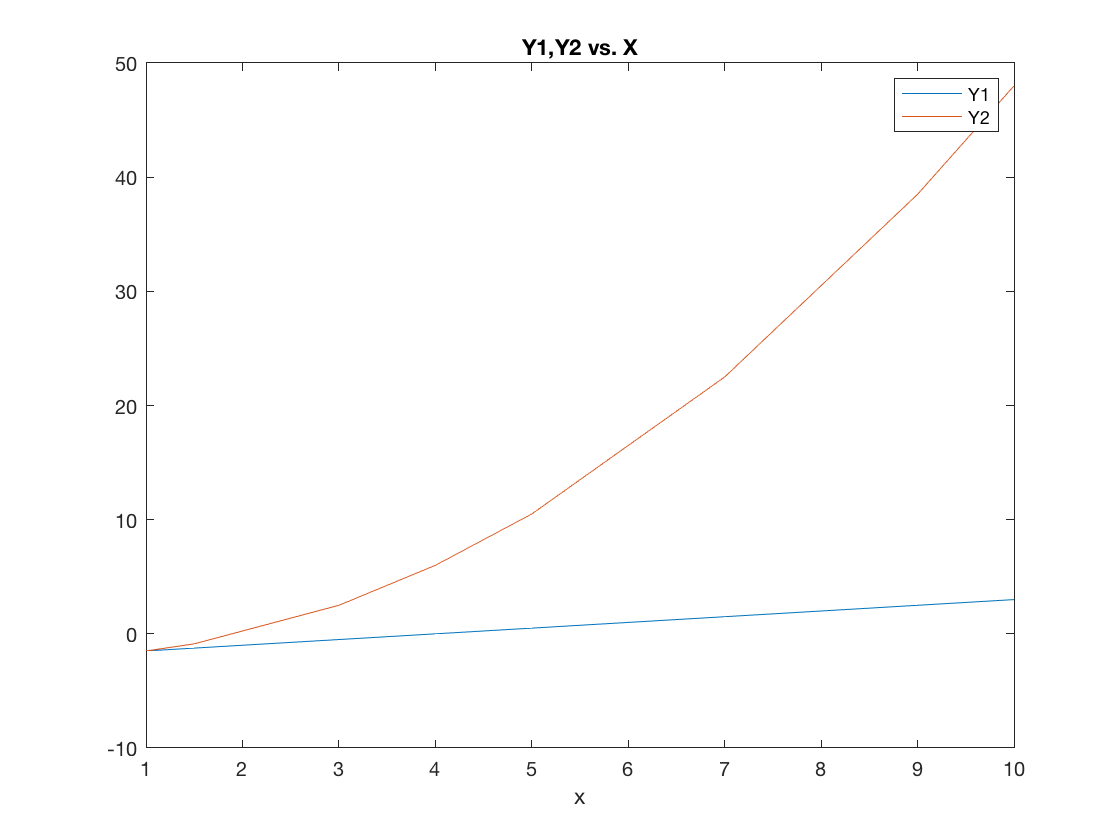


% Plot Y1, Y2 vs X
figure
plot(x, y1, x, y2)
title("Y1,Y2 vs. X")
xlabel("x")
legend("Y1", "Y2")

## Question 2

Code:

% Create x vector
x=linspace(-10, 20, 200)';

% Calculate and display sum of the elements of x
sum_x=sum(x)

sum_x = 1000

## Question 3

Code:

% Create A matrix
A=[2, 4, 6; 1, 7, 5; 3, 12, 4];

% Create vector b
b=[-2;3;10];

% Calculate and display C=A'b
C=A'*b

C =     29
   133
    43



% Calculate and display D=((A'A)^(-1))*b
D=inv(A'*A)*b

D =    -3.2505
    0.3961
    0.8037



% Calculate and Display E= sum_i (sum_j aij*bi)
E=sum(sum(A.*b))

E = 205


% F matrix is matrix with the 2nd row and 3rd column deleted

% Initialize F to A
F=A;

% Delete 2nd row
F(2,:) = [];

% Delete 3rd column and display F
F(:,3)=[]

F =      2     4
     3    12



% Solve the system Ax=b
x=A\b

x =    -0.1622
    1.2432
   -1.1081


## Question 4

Code:

% Create block diagonal matrix

% Initialize B to a 15 x 15 zero matrix
B=blkdiag(A,A,A,A,A)

## Question 5

Code:

% Create 5x3 matrix of randome distributions with mu= 10 and std=5

A=10+5*randn(5,3)

A =    12.6883    3.4616    3.2506
   19.1694    7.8320   25.1746
   -1.2942   11.7131   13.6270
   14.3109   27.8920    9.6847
   11.5938   23.8472   13.5737



% Replace the elements of A that are less than 10 with 0
A(A<10)=0;

% Replace the elements of A that are equal or greater tan 10 with 1
A(A>=10)=1

A =      1     0     0
     1     0     1
     0     1     1
     1     1     0
     1     1     1


## Question 6

Code:

% Import CSV file
data = csvread('datahw1.csv');

T=readtable('datahw1.csv', 'ReadVariableNames', false);

% Modify variable names
T.Properties.VariableNames = {'FirmID', 'Year', 'Export', 'RD', 'prod', 'cap'}

fitlm(T,'prod~Export+RD+cap')